clearvars; clear all;

filename = "C:\Users\kanis\p2slam_datasets\DS1\channels.mat";
[channels, RSSI, labels, labels_vel, opt, ap_locations, ap_angles, grid] = extractCSIDataFromP2SLAM(filename);

Loaded channel matrix with dimensions: 34208 x 234 x 5 x 4
RSSI matrix dimensions: 34208 x 5
Position labels dimensions: 34208 x 2
Velocity Labels dimensions: 34208 x 1
Number of frequency points: 234

Summary Statistics:
Frequency range: 5736.88 MHz to 5813.12 MHz
Wavelength range: 51.61 mm to 52.29 mm
Grid size: 31.67 m x 33.06 m


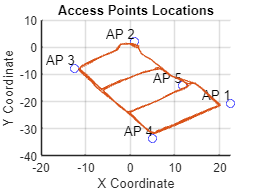

% Extract x and y coordinates
x_coords = ap_locations(:, 1);
y_coords = ap_locations(:, 2);

% Create a scatter plot of the access points
figure;
scatter(x_coords, y_coords, 'bo');
hold on;

% Add labels to each access point
for i = 1:length(x_coords)
    label = sprintf('AP %d', i);
    text(x_coords(i), y_coords(i), label, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

plot(labels(:, 1), labels(:, 2))

% Set axis labels and title
xlabel('X Coordinate');
ylabel('Y Coordinate');
title('Access Points Locations');
grid on;
hold off;

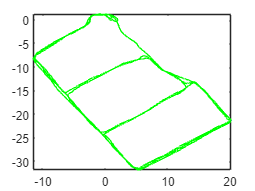

% Calculate GT AoA and Verify
aoa_gnd = computeAngleOfArrival(labels(:, 1:2), ap_locations, ap_angles);
verify_aoa = zeros(size(labels, 1), 2);
for i=1:size(labels, 1)
    verify_aoa(i, :) = lineIntersect2D_slope_point((aoa_gnd(i, :) + ap_angles')', ap_locations(:, 1), ap_locations(:, 1), eye(5));
end
figure;
plot(labels(:, 1), labels(:, 2), "b");
hold on;
plot(verify_aoa(:, 1), verify_aoa(:, 2), "g");

dataset = "DS1";
DATA_SAVE_TOP = "C:\Users\kanis\p2slam_features";

n_points = size(channels, 1);
n_ap = size(channels, 3);    

% Theta Vals and D_vals
theta_vals = linspace(-pi/2, pi/2, 360);
d_vals = linspace(-10, 30, 400);    

% Creates Directories if they don't already exist
if ~exist(fullfile(DATA_SAVE_TOP,dataset), 'dir')
    mkdir(fullfile(DATA_SAVE_TOP,dataset))
end
if ~exist(fullfile(DATA_SAVE_TOP,dataset,'features_aoa'), 'dir')
    mkdir(fullfile(DATA_SAVE_TOP,dataset,'features_aoa'))
end
if ~exist(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind'), 'dir')
    mkdir(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind'))
end    

% Save ap.h5 file
try
    h5create(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa', 'ap.h5'),...
        '/aps', size(ap_locations));
    h5create(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa', 'ap.h5'),...
        '/ap_aoas', size(ap_angles));
catch
    disp('AP File already exists');
end
h5write(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa', 'ap.h5'),...
    '/aps',ap_locations);
h5write(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa', 'ap.h5'),...
    '/ap_aoas', ap_angles);

for i=1:n_points
    features_2d = generate_aoa_tof_features(squeeze(channels(i,:,:,:)), ap_locations, theta_vals, d_vals, opt);        
    
    % Save Individual AP Data Files
    if (mod(i,1000)==0)
        fprintf('Saving....%d.h5\n',i);
    end

    fname = [num2str(i),'.h5'];

    try
        h5create(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind',fname),...
            '/features_2d',size(features_2d));
        h5create(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind',fname),...
            '/aoa_gnd',size(aoa_gnd(i, :),2));
        h5create(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind',fname),...
            '/labels',size(labels(i, :),2));
        h5create(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa', 'ind', fname),...
            '/labels_vel', size(labels_vel(i, :), 2))
        h5create(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa', 'ind', fname),...
            '/rssi', size(RSSI(i, :), 2))
    catch
        disp('Files already exist');
    end

    h5write(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind',fname),...
        '/features_2d', features_2d);
    h5write(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind',fname),...
        '/aoa_gnd', squeeze(aoa_gnd(i, :)));
    h5write(fullfile(DATA_SAVE_TOP,dataset,'features_aoa','ind',fname),...
        '/labels', squeeze(labels(i, :)));
    h5write(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa','ind', fname),...
        '/labels_vel', squeeze(labels_vel(i, :)));
    h5write(fullfile(DATA_SAVE_TOP, dataset, 'features_aoa', 'ind', fname),...
        '/rssi', squeeze(RSSI(i, :)));
end

Saving....1000.h5
Saving....2000.h5
Saving....3000.h5
Saving....4000.h5
Saving....5000.h5
Saving....6000.h5
Saving....7000.h5
Saving....8000.h5
Saving....9000.h5
Saving....10000.h5
Saving....11000.h5
Saving....12000.h5
Saving....13000.h5
Saving....14000.h5
Saving....15000.h5
Saving....16000.h5
Saving....17000.h5
Saving....18000.h5
Saving....19000.h5
Saving....20000.h5
Saving....21000.h5
Saving....22000.h5
Saving....23000.h5
Saving....24000.h5
Saving....25000.h5
Saving....26000.h5
Saving....27000.h5
Saving....28000.h5
Saving....29000.h5
Saving....30000.h5
Saving....31000.h5
Saving....32000.h5
Saving....33000.h5
Saving....34000.h5
